clear


a0 = 2;
b0 = 1;
c0 = -1;

n = 10;

u = randn(1, n);

sigma = 50;

X = 1:n;
Y = a0*X.^2 + b0*X + c0 + sigma*u;


X2 = X;
Y2 = Y;
for i = 1:length(X2)
    X2(i) = X2(i) * X(i);
    Y2(i) = Y2(i) * X(i);
end

X3 = X2;
Y3 = Y2;
for i = 1:length(X3)
    X3(i) = X3(i) * X(i);
    Y3(i) = Y3(i) * X(i);
end

X4 = X3;
for i = 1:length(X4)
    X4(i) = X4(i) * X(i);
end


A = [sum(X4), sum(X3), sum(X2);
     sum(X3), sum(X2), sum(X) ;
     sum(X2), sum(X) , n      ];
B = [sum(Y3);
     sum(Y2);
     sum(Y) ];

coeffs = linsolve(A, B);
a = coeffs(1);
b = coeffs(2);
c = coeffs(3);


podgonka = a*X.^2 + b*X + c

podgonka =   -40.0380  -27.2521  -10.1708   11.2060   36.8782   66.8460  101.1092  139.6679  182.5220  229.6716


nevyazka = Y - podgonka

nevyazka =    41.4496  -63.7248  -14.2300    2.7989   51.8507    2.0164    7.9697   -5.5608  -60.5384   37.9686



skal = dot(podgonka, nevyazka);


sn = sqrt(sum(nevyazka.^2)/(n))

sn = 37.2596

% gamma = 0.95;
% tg = 1.96;
gamma = 0.90;
tg = 1.645;

ppp = (tg*sn/sqrt(n))*sqrt(1 + (X-sum(X)/n).^2/(sum((X-sum(X)/n).^2)/(n-1)));

f_plus = podgonka + ppp;
f_minus = podgonka - ppp;


a0

a0 = 2

b0

b0 = 1

c0

c0 = -1

a

a = 2.1477

b

b = 6.3426

c

c = -48.5283


skal

skal = -2.7285e-12

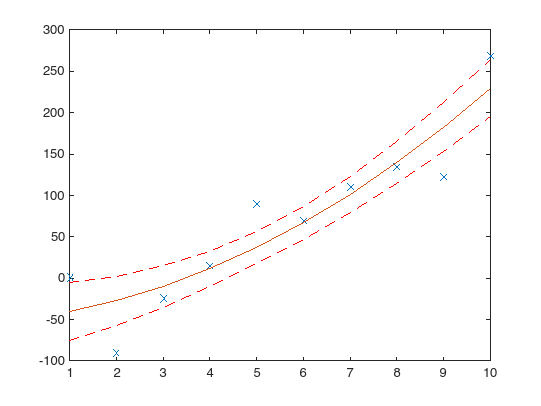


plot(X, Y, "x")
hold on
plot(X, podgonka)
plot(X, f_plus, "--r")
plot(X, f_minus, "--r")